%Instable condition
u = 30;
D = 8;

t_start = 0;
t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space = (x_final - x_start)/dx;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);

if (4*(alpha^2) < 2*beta && 2*beta < 1)
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability not respected!


% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
T = zeros(n_step_space,n_step_time);
for i = 2:n_step_space-1
    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end

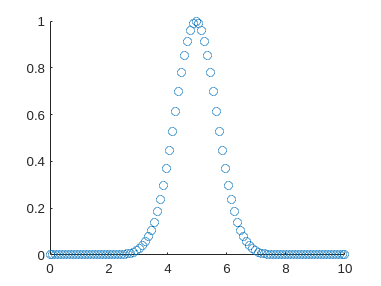

scatter(x, T(:,1))    

% Scheme matrix definition

M = zeros(n_step_space, n_step_space);
for i = 1:n_step_space
    M(i,i) = 1+2*beta;
    if (i ~= 1) 
        M(i, i-1) = -(alpha+beta);
    end

    if (i ~= n_step_space)
        M(i, i+1) = alpha - beta;
    end

end

M(1,2) = 0;
M(n_step_space , n_step_space-1) = 0;

D = diag(diag(M));
P = M - D;

epsilon = 0.0001;
count_max = 10000;

for j = 2:n_step_time
    b = T(:,j-1);
    sol = b;
    e = M*sol - b;
    count = 0;
    while (max(e) > epsilon && count < count_max)
        %x =  x - inv(D)*e;
        sol = sol - D\e;
        e = M*sol - b;
        count = count + 1;
    end
    T(:,j) = sol;
end


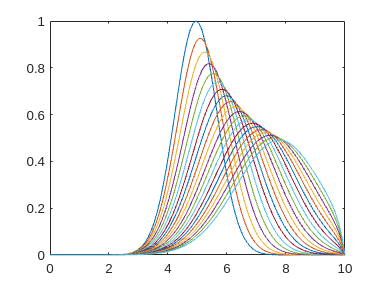


for j = 1:5:n_step_time
    plot(x, T(:,j));
    hold on
end
hold off

for j = 1:n_step_time
    plot(x, T(:,j))
    ylim([0,1])
    pause (0.3)
end

%--------------------------------------------------

%Pretty condtions but with a spike
u = 30;
D = 4;

t_start = 0;
t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space = (x_final - x_start)/dx;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);

if (4*(alpha^2) < 2*beta && 2*beta < 1)
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability respected!


% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
T = zeros(n_step_space,n_step_time);
for i = 2:n_step_space-1
    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end

scatter(x, T(:,1))    

% Scheme matrix definition

M = zeros(n_step_space, n_step_space);
for i = 1:n_step_space
    M(i,i) = 1+2*beta;
    if (i ~= 1) 
        M(i, i-1) = -(alpha+beta);
    end

    if (i ~= n_step_space)
        M(i, i+1) = alpha - beta;
    end

end

M(1,2) = 0;
M(n_step_space , n_step_space-1) = 0;

D = diag(diag(M));
P = M - D;

epsilon = 0.0001;
count_max = 10000;

for j = 2:n_step_time
    b = T(:,j-1);
    sol = b;
    e = M*sol - b;
    count = 0;
    while (max(e) > epsilon && count < count_max)
        %x =  x - inv(D)*e;
        sol = sol - D\e;
        e = M*sol - b;
        count = count + 1;
    end
    T(:,j) = sol;

     %Spike
    if (j == 35) 
        T(75,j) = 1; 
    end
end


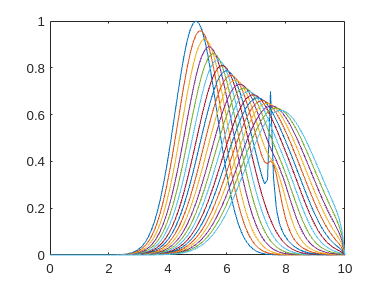

for j = 1:5:n_step_time
    plot(x, T(:,j));
    hold on
end
hold off

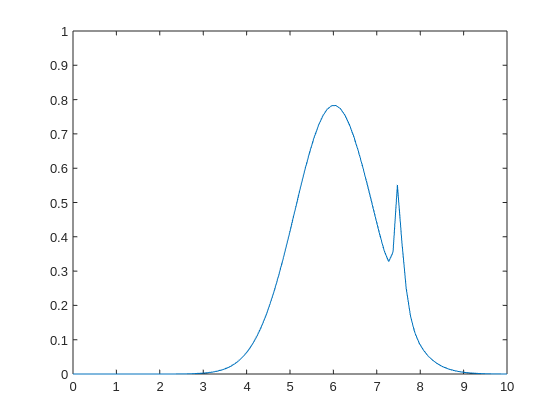

for j = 1:n_step_time
    plot(x, T(:,j))
    ylim([0,1])
    pause (0.3)
end